clear
clc
close all 

% Define the time horizon 
T = 50;

% Define the system matrices
A = [0 1; 0 0];
B = [0; 1];

% Definte cost matrices 
Q = [1 0; 0 1]; 
R = 1; 
R_inv= 1 / R; 

% Define the initial state of the system
x0 = [5; 5];

% Compute the solution of the Algebraic Riccati equation
P = icare(A, B, Q, R)

P =     1.7321    1.0000
    1.0000    1.7321


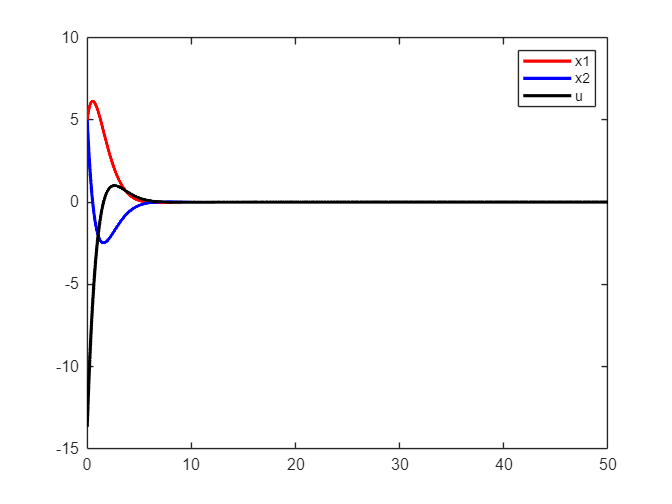


K = - (R) ^ (-1) * (B' * P);
Acl = A + B * K; 

opts = odeset('RelTol', 1e-9, 'AbsTol', 1e-9);
[t, x] = ode45(@(t, x) Acl * x, [0 T], x0, opts);
x = x';

% Optimal control along the trajectory:
u = K * x;

% State and control output
plot(t, x(1, :), 'r', 'LineWidth', 2)
hold on
plot(t, x(2, :), 'b', 'LineWidth', 2)
hold on
plot(t, u, 'k', 'LineWidth', 2)
hold off

legend('x1', 'x2', 'u')


% Instantaneous cost along the trajectory
XQX = sum(x .* (Q * x), 1);      % x'Qx at each time
URU = R * (u .^ 2);              % u'Ru at each time
L   = XQX + URU;                 % running cost

% 1) Numerical integral up to T
J_num = trapz(t, L'); 

% 2) Analytic identity using P from CARE
xT   = x(:, end);
J_ana = x0' * P * x0 - xT' * P * xT;

fprintf('Numerical cost up to T:   %.12f\n', J_num);

Numerical cost up to T:   136.607828447734


fprintf('Analytic cost up to T:    %.12f\n', J_ana);

Analytic cost up to T:    136.602540378444


fprintf('Absolute difference:      %.3e\n', abs(J_num - J_ana));

Absolute difference:      5.288e-03
